clear
% Define the folder path
%folderPath = 'HDR/JPG'; % Adjust the path as necessary
%folderPath = 'images'; % Adjust the path as necessary
folderPath = 'HDR/Strommen';
folderPath = 'images/Visualiseringcentret/aligned'

folderPath = 'images/Visualiseringcentret/aligned'


% Create an imageDatastore for all JPG files in the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.JPG');
%imds = imageDatastore(folderPath, 'FileExtensions', '.jfif');

% Display the number of images found
numImages = numel(imds.Files);
disp(['Number of JPG images found: ', num2str(numImages)]);

Number of JPG images found: 10


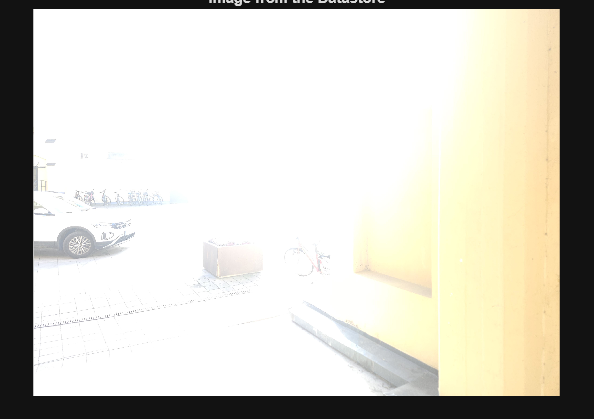


% Read the i-th image from the datastore
img = readimage(imds, 1);

% Display the image
imshow(img);
title('Image from the Datastore');

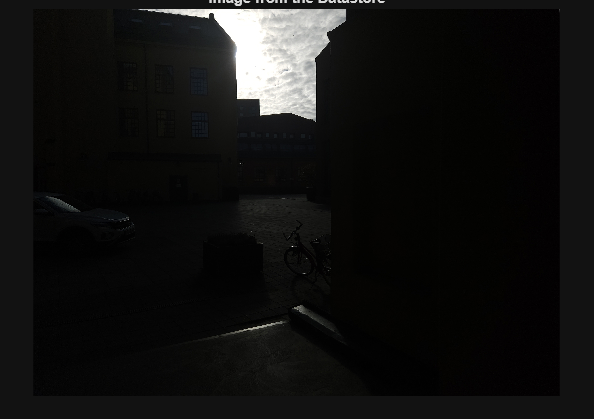

img = readimage(imds, numImages);
imshow(img);
title('Image from the Datastore');


%Ranom Sampling of pixels
[H, W, C] = size(img); % read image Height, Width, Channel. Assumed same for all images duuh

numSamples = 200;
rng();

% meshgrid avoids sample clustering. grid bias + random.
[Xs, Ys] = meshgrid(round(linspace(1,W,round(sqrt(numSamples)))), round(linspace(1,H,sqrt(numSamples))));
coord = [Xs(:),Ys(:)];
if size(coord, 1) < numSamples
    extra = numSamples - size(coord,1);
    randCoord = [randi(W, extra, 1), randi(H, extra, 1)];
    coord = [coord; randCoord];
else
    coord = coord(1:numSamples,:);
end
% I orginal artikeln så nämns det att de kastade även ut väldigt saturerade
% värden dvs 255


%Get exposure times from images
exposureTimes = zeros(numImages,1);
for j = 1:numImages
    info = imfinfo(imds.Files{j});
    %if(exist('info.DigitalCamera.ExposureTime'))
        %exposureTimes(j) = info.DigitalCamera.ExposureTime;
    %else
        %exposureTimes = [1/8000; 1/6400; 1/3200; 1/1600; 1/800; 1/400; 1/200; 1/100; 1/50]; %for kärleksparksbilden
        exposureTimes = [1/50; 1/90; 1/180; 1/250; 1/1500; 1/2000; 1/3000; 1/4000; 1/8000; 1/12000]; %for Visualiseringcentret
    %end
end

B = log(exposureTimes);


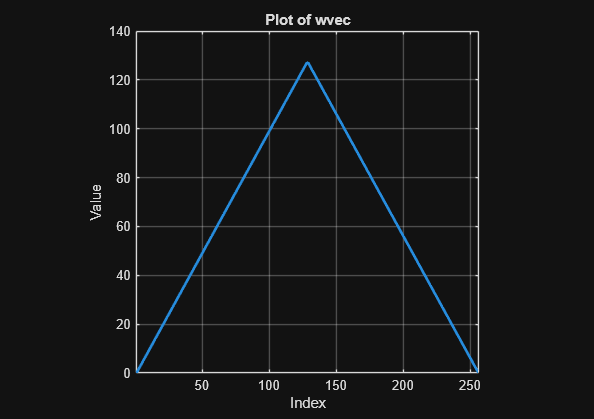


% Hat weight 
clf
Zmin = 0;
Zmax = 255;
Zmid = Zmax/2;
wvec = zeros(256, 1);
for z = Zmin:Zmax
    if z <= Zmid
        wvec(z+1) = z - Zmin;
    else
        wvec(z+1) = Zmax -z;
    end
end

wvec3D = {wvec,wvec,wvec};

% Plot wvec against its indices
plot(wvec3D{1}, 'LineWidth', 2);
xlim([1 length(wvec3D{1})]);
title('Plot of wvec');
xlabel('Index');
ylabel('Value');
grid on
axis square;


% Sample pixel values for each channel separately
%Z_red   = zeros(numSamples, numImages);
%Z_green = zeros(numSamples, numImages);
%Z_blue  = zeros(numSamples, numImages);
Z_red = [];
Z_green = [];
Z_blue = [];
%Z_red   = NaN(numSamples, numImages);
%Z_green = NaN(numSamples, numImages);
%Z_blue  = NaN(numSamples, numImages);

Z_clip_min = 5;
Z_clip_max = 250;

for j = 1:numImages
    Ij = rgb2lin(im2double(readimage(imds, j)));

    for i = 1:numSamples
      
       Ztemp = round(Ij(coord(i,2), coord(i,1),:) * 255);
        
       % Store all raw pixel values
       Z_red(i,j)   = Ztemp(1);
       Z_green(i,j) = Ztemp(2);
       Z_blue(i,j)  = Ztemp(3);
    end
end


disp(['Number of samples per channel: ', num2str(numel(Z_red)/numImages)]);

Number of samples per channel: 200



%run gsolve
lambda = 200;
[g_red, lE_red] = gsolve(Z_red, B, lambda, wvec);

[g_green, lE_green] = gsolve(Z_green, B, lambda, wvec);

[g_blue, lE_blue] = gsolve(Z_blue, B, lambda, wvec);


% Combine into a singular g
g = {g_red, g_green, g_blue};



% Read camera curve, named gfun
load("HDR\gfun.mat")

% Convert gfun to 1x3 cell array
gfunE = cell(1, C);
for ch = 1:C
    gfunE{ch} = gfun(:, ch);
end


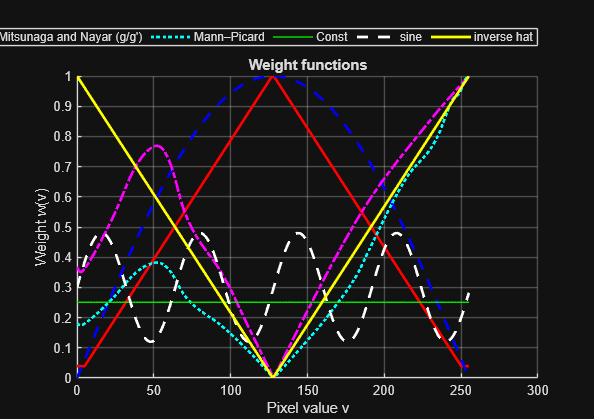

%New weight function part
clf

cols = {'r','g','b'};
Zmin = 0; Zmax = 255;
v = (Zmin:Zmax)';

% how many codes to ignore at each end (prevents clip influence)
MARGIN = 0;              
% smoothing & derivative floor for g-based weights
SMOOTH_WIN = 9;           % odd; 7–13 
GP_FLOOR   = 1e-2;        % prevents division by tiny gradients

% Convenience: zero out margins helper
mask_mid = (v > MARGIN) & (v < Zmax - MARGIN);

% --- 0) Constant (reference) ---    
w_const = repmat({64 / 255 * ones(256,1)}, 1, 3);

% --- 1) Debevec hat (robust default) ---
w_hat_vec = max(5, min(v - MARGIN, (Zmax - MARGIN) - v));
%w_hat_vec(~mask_mid) = 0;
w_hat_vec = w_hat_vec / max(w_hat_vec);
w_hat = {w_hat_vec, w_hat_vec, w_hat_vec};

% --- 2) Reinhard SNR-like (smooth bell) ---
u = (v - MARGIN) / (Zmax - 2*MARGIN);            % 0..1 inside the mid range
w_rein_vec = zeros(size(v));
inside = (u > 0) & (u < 1);
w_rein_vec(inside) = sin(pi * u(inside));        % smooth, zero at ends
w_rein_vec = w_rein_vec / max(w_rein_vec);
w_reinhard = {w_rein_vec, w_rein_vec, w_rein_vec};

% --- 3) Szeliski/Mitsunaga–Nayar: w = g / g' (stabilized) ---
w_szel = cell(1,3);
% --- 4) Mann–Picard: w = 1 / d(log g) (stabilized) ---
w_mp   = cell(1,3);

% --- 5) wave-shaped
w_jagged_vec = 0.3 + 0.3*(0.6*sin(2*pi*v/64));

% Pack into RGB cell array for your HDR code
w_jagged = {w_jagged_vec, w_jagged_vec, w_jagged_vec};

% --- 6) Inverse hat
w_invhat_vec = max(0, abs(v - Zmax/2));   % distance from the center
w_invhat_vec = w_invhat_vec / max(w_invhat_vec);  % normalize 0–1
w_invhat = {w_invhat_vec, w_invhat_vec, w_invhat_vec};


for ch = 1:3
    gvec = g{ch};                                % your recovered CRF
    % smooth g to tame noise at the ends before taking gradients
    g_s = smoothdata(gvec, SMOOTH_WIN, 'loess');

    % stabilized derivative
    gp = gradient(g_s);
    % floor derivative magnitude to avoid huge weights
    gp = sign(gp) .* max(abs(gp), GP_FLOOR);

    % 3) w = g / g'
    w3 = g_s ./ gp;
    %w3(~isfinite(w3)) = 0;
    %w3(~mask_mid)     = 0;
    %w3 = max(w3,0);
    w3 = w3 / max(w3 + eps);
    w_szel{ch} = abs(w3);

    % 4) Mann–Picard: 1 / d(log g)
    gl = log(g_s + eps);
    dgl = gradient(gl);
    %dgl = sign(dgl) .* max(abs(dgl), GP_FLOOR);
    wmp = 1 ./ dgl;
    %wmp(~isfinite(wmp)) = 0;
    %wmp(~mask_mid)      = 0;
    %wmp = max(wmp,0);
    wmp = wmp / max(wmp + eps);
    w_mp{ch} = abs(wmp);

end

% ---------- Plot (one figure, all variants) ----------
figure(1); hold on; grid on;
plot(v, w_hat_vec,     'r-',  'LineWidth', 2)
plot(v, w_rein_vec,    'b--', 'LineWidth', 2)
plot(v, w_szel{2},     'm-.', 'LineWidth', 2)   % show G channel as representative
plot(v, w_mp{2},       'c:',  'LineWidth', 2)
plot(v, w_const{2},   'g-',  'LineWidth', 1)
plot(v, w_jagged{2}, 'w--', 'LineWidth', 2)
plot(v, w_invhat{2}, 'y-', 'LineWidth', 2)
title('Weight functions');
xlabel('Pixel value v'); ylabel('Weight w(v)');
legend({'Hat (Debevec)','Reinhard SNR','Mitsunaga and Nayar (g/g'')','Mann–Picard','Const', 'sine', 'inverse hat'}, ...
       'Location','northoutside','Orientation','horizontal');


%Load all images (now with colour)
for j = 1:numImages

    Ij = rgb2lin(im2double(readimage(imds, j)));
    %Ij = readimage(imds,j);
    %Ij = rgb2lin(Ij); %sRGB to linear RGB behövs för korrekt algo
    %No CIELAB should be used because the algoritim needs accurate
    %radiometric values

    if j == 1 
        [H,W,C] = size(Ij);
        images = zeros(H,W,C,numImages);

    end 
    images(:,:,:,j) = Ij;
end 



%reconstruct image in .hdr (Radiance) with hatweight wvec
lnE = reconstructHDRszliski(H,W,C,numImages,images, B,wvec3D, g);


%with w = g(z)/g'(z)
lnE_szliski = reconstructHDRszliski(H,W,C,numImages,images, B, w_szel, g);
lnE_mp = reconstructHDRszliski(H,W,C,numImages,images, B, w_mp, g);
lnE_reinhard = reconstructHDRszliski(H,W,C,numImages,images, B, w_reinhard, g);
lnE_const = reconstructHDRszliski(H,W,C,numImages,images, B, w_const, g);
lnE_jagged = reconstructHDRszliski(H,W,C,numImages,images, B, w_jagged, g);
lnE_invhat = reconstructHDRszliski(H,W,C,numImages,images, B, w_invhat, g);

function [lnE] = reconstructHDRszliski(H, W, C,numImages, images, exposureTimes, weight, respCurveG) %takes weight as cell(1,3)

   lnE = ones(H,W,C);
  
%for improved weight
for ch = 1:C
    for y = 1:H
        for x = 1:W
            num = 0;
            den = 0;
            for j = 1:numImages
                % Pixel value in [0,255] for channel ch
                z = round(images(y,x,ch,j) * 255);

                % Clamp
                z = max(0, min(255, z));

                wij = weight{ch}(z+1);
                if(wij == 0)
                    continue; %skip pixel
                end
                num = num + wij * (respCurveG{ch}(z+1) - exposureTimes(j));  % per channel
                den = den + wij;
            end

            if den > 0
                lnE(y,x,ch) = num / den;
            else
                lnE(y,x,ch) = 0;
            end
        end
    end
end
end


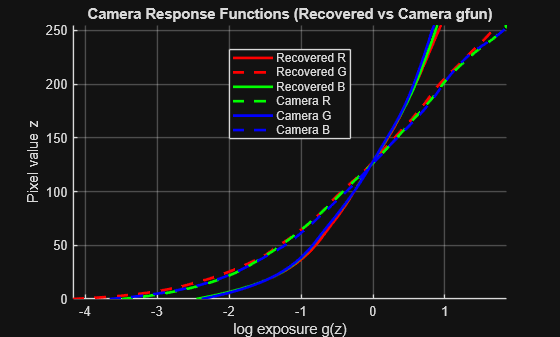


%reconstruct image in .hdr with camera response (Radiance) 
lnE_cam = reconstructHDRszliski(H,W,C,numImages, images, B, w_hat, gfunE);
lnE_cam_szliski = reconstructHDRszliski(H,W,C,numImages, images, B, w_szel, gfunE);


figure; hold on;

cols = {'r','g','b'};
labels = {'Recovered R','Recovered G','Recovered B', ...
          'Camera R','Camera G','Camera B'};

for ch = 1:3
    % recovered
    plot(g{ch}, 0:255, cols{ch}, 'LineWidth', 2);
    % camera-provided (dashed)
    plot(gfunE{ch}, 0:255, [cols{ch} '--'], 'LineWidth', 2);
end

ylabel('Pixel value z');
xlabel('log exposure g(z)');
title('Camera Response Functions (Recovered vs Camera gfun)');
legend(labels, 'Location','best');
grid on;
axis tight;

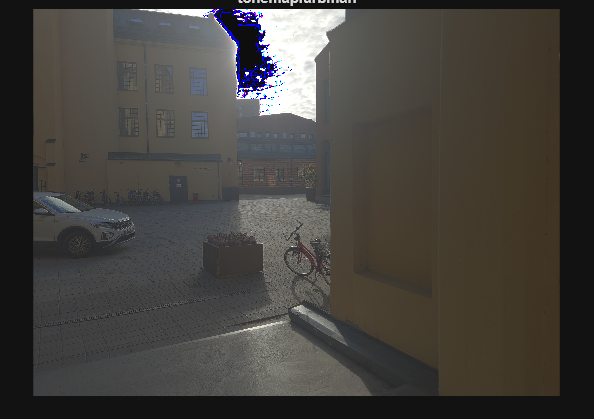


clf

HDR = exp(lnE);
%HDR3 = repmat(HDR, [1, 1, 3])
%hdrwrite(single(HDR), 'result.hdr'); 
%Result blir nästan helt vit när man kollar i photoshop
% hade dock inte hdr-läge på men men. 

% Nu använder den:
% edge-preserving decompositions for multiscale tone and detail manipulation
% tonemap men vi ska göra egen eller något sånt. 
LDR_final = tonemapfarbman(HDR, 'Exposure', 2.2);
%LDR_final = tonemapfarbman(HDR);
imshow(LDR_final)
title('tonemapfarbman')

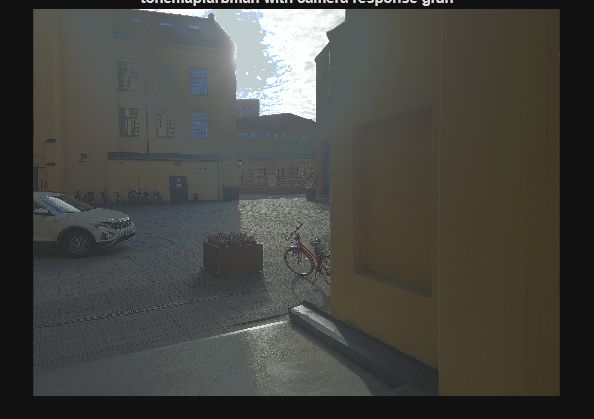


HDR_cam = exp(lnE_cam);
LDR_final_cam = tonemapfarbman(HDR_cam, 'Exposure', 1.2);
imshow(LDR_final_cam)
title('tonemapfarbman with camera response gfun')

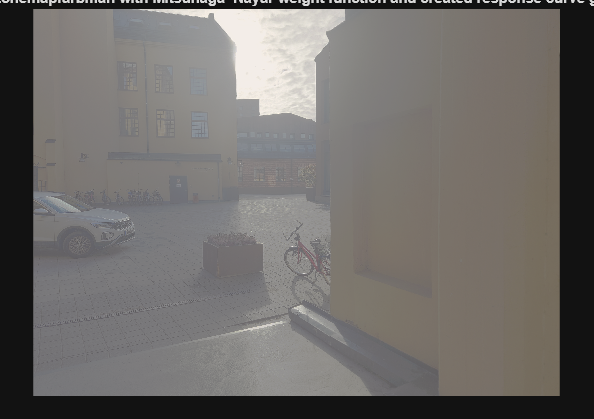


HDR_szliski = exp(lnE_szliski);
LDR_final_szliski = tonemapfarbman(HDR_szliski, "Exposure", .8);
imshow(LDR_final_szliski)
title('tonemapfarbman with Mitsunaga–Nayar weight function and created response curve g')

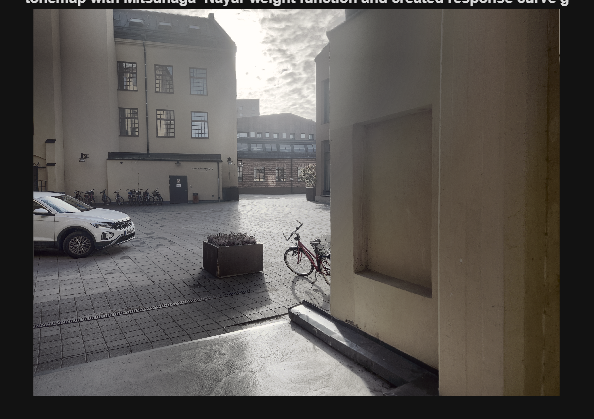


LDR_final_szliski_n = tonemap(HDR_szliski);
imshow(LDR_final_szliski_n)
title('tonemap with Mitsunaga–Nayar weight function and created response curve g')

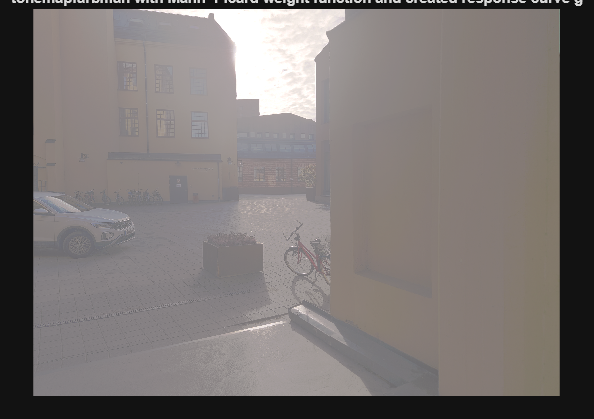


HDR_mp = exp(lnE_mp);
LDR_final_mp = tonemapfarbman(HDR_mp, 'Exposure', 1.2);
imshow(LDR_final_mp)
title('tonemapfarbman with Mann–Picard weight function and created response curve g')

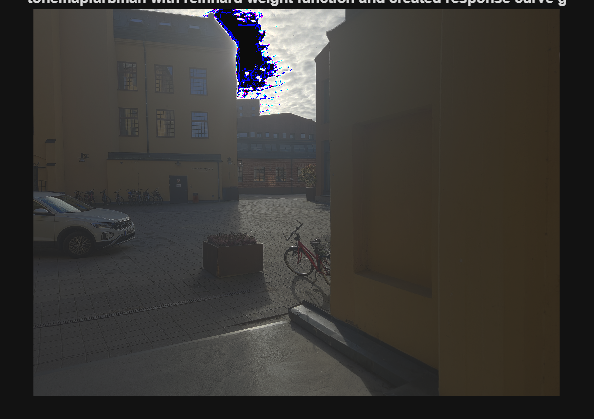


HDR_reinhard = exp(lnE_reinhard);
LDR_final_reinhard = tonemapfarbman(HDR_reinhard, 'Exposure', 1.2);
imshow(LDR_final_reinhard)
title('tonemapfarbman with reinhard weight function and created response curve g')

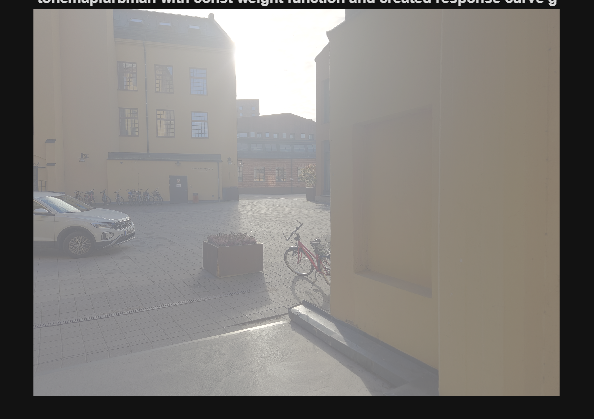


HDR_const = exp(lnE_const);
LDR_final_const = tonemapfarbman(HDR_const, 'Exposure', 1.2);
imshow(LDR_final_const)
title('tonemapfarbman with const weight function and created response curve g')

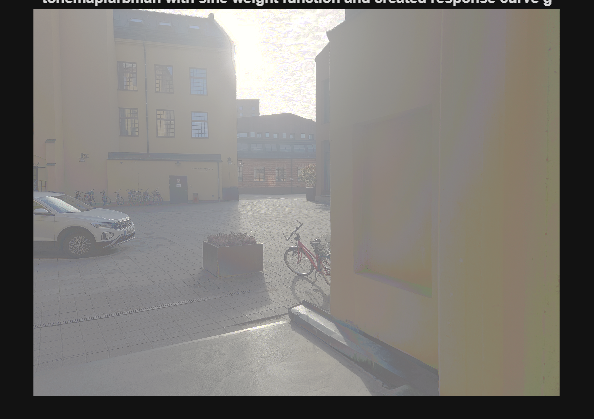


HDR_jagged = exp(lnE_jagged);
LDR_final_jagged = tonemapfarbman(HDR_jagged, 'Exposure', 1.2);
imshow(LDR_final_jagged)
title('tonemapfarbman with sine weight function and created response curve g')

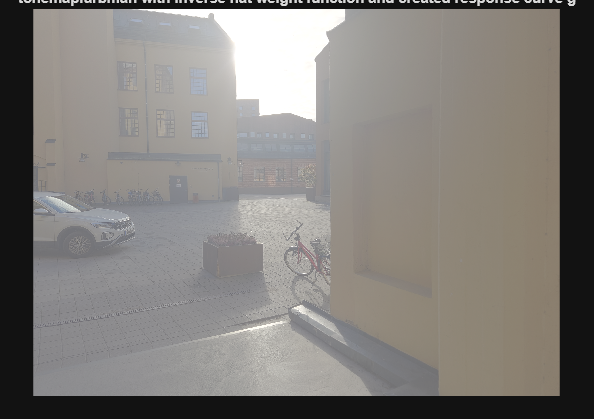


HDR_invhat = exp(lnE_const);
LDR_final_invhat = tonemapfarbman(HDR_invhat, 'Exposure', 1.2);
imshow(LDR_final_invhat)
title('tonemapfarbman with inverse hat weight function and created response curve g')

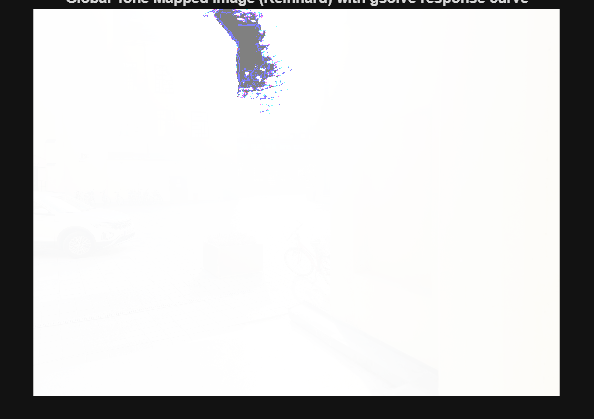


% Apply the global tone mapping filter                  Reinhard
Vin = HDR;
Vout = Vin ./ (Vin + 1);

% Display the original and tone-mapped images
figure;
imshow(Vout);
title('Global Tone Mapped Image (Reinhard) with gsolve response curve');

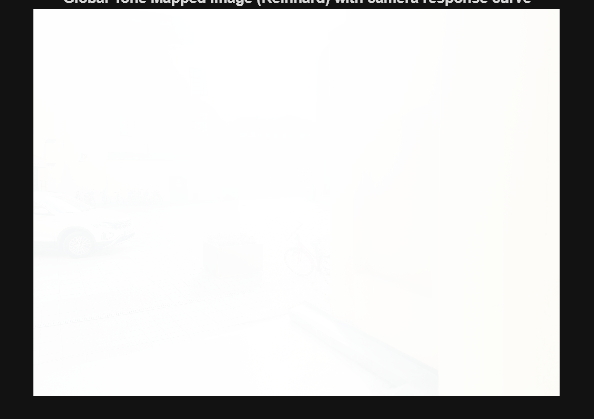


Vin = HDR_cam;
Vout = Vin ./ (Vin + 1);

imshow(Vout);
title('Global Tone Mapped Image (Reinhard) with camera response curve');

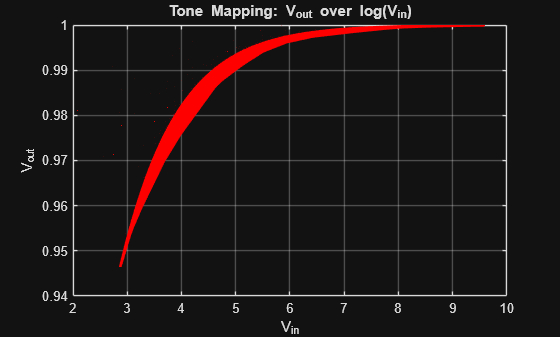


figure;
plot(log(Vin(:,:,1)), Vout(:,:,1), 'r-', 'LineWidth', 2);
hold on
%plot(log(Vin(:,:,2)), Vout(:,:,2), 'g-', 'LineWidth', 2);
%plot(log(Vin(:,:,3)), Vout(:,:,3), 'b-', 'LineWidth', 2);
title('Tone Mapping: V_{out} over log(V_{in})');
xlabel('V_{in}');
ylabel('V_{out}');
grid on;
hold off


% This section is from the paper 
% HDR-Debevec-97.pdf


% gsolve.m − Solve for imaging system response function
%
% Given a set of pixel values observed for several pixels in several
% images with different exposure times, this function returns the
% imaging system's response function g as well as the log film irradiance
% values for the observed pixels.
%
% Assumes:
%
% Zmin = 0
% Zmax = 255
%
% Arguments:
%
% Z(i,j) is the pixel values of pixel location number i in image j
% B(j) is the log delta t, or log shutter speed, for image j
% l is lamdba, the constant that determines the amount of smoothness
% w(z) is the weighting function value for pixel value z
% 
% Returns:
%
% g(z) is the log exposure corresponding to pixel value z
% lE(i) is the log film irradiance at pixel location i
%

function [g,lE]=gsolve(Z,B,l,w)

    n = 256;
    A = zeros(size(Z,1)*size(Z,2)+n+1,n+size(Z,1));
    b = zeros(size(A,1),1);
    %% Include the data−fitting equations
    k = 1;
    for i=1:size(Z,1)
        for j=1:size(Z,2)
            wij = w(Z(i,j)+1);
            A(k,Z(i,j)+1) = wij; 
            A(k,n+i) = -wij; 
            b(k,1) = wij * B(j);
            k=k+1;
        end
    end
    %% Fix the curve by setting its middle value to 0
    A(k,129) = 1;
    k=k+1;
    %% Include the smoothness equations
    for i=1:n-2
     A(k,i)=l*w(i+1); A(k,i+1)=-2*l*w(i+1); A(k,i+2)=l*w(i+1);
     k=k+1;
    end
    %% Solve the system using SVD
    x = A\b;
    g = x(1:n);
    lE = x(n+1:size(x,1));
end

